% First generate a vector of x points, equally spaced in the interval [0,2.5], and then evaluate erf(x) at those points.
x = (0:0.1:2.5)';
y = erf(x);

% Determine the coefficients of the approximating polynomial of degree 6.
p = polyfit(x,y,6)

p =     0.0084   -0.0983    0.4217   -0.7435    0.1471    1.1064    0.0004



% To see how good the fit is, evaluate the polynomial at the data points and generate a table showing the data, fit, and error.
f = polyval(p,x);
T = table(x,y,f,y-f,'VariableNames',{'X','Y','Fit','FitError'})

T = 26×4 table
     X        Y          Fit         FitError  
    ___    _______    __________    ___________

      0          0    0.00044117    -0.00044117
    0.1    0.11246       0.11185     0.00060836
    0.2     0.2227       0.22231     0.00039189
    0.3    0.32863       0.32872    -9.7429e-05
    0.4    0.42839        0.4288    -0.00040661
    0.5     0.5205       0.52093    -0.00042568
    0.6    0.60386       0.60408    -0.00022824
    0.7     0.6778       0.67775     4.6383e-05
    0.8     0.7421       0.74183     0.00026992
    0.9    0.79691       0.79654     0.00036515
      1     0.8427       0.84238      0.0003164
    1.1    0.88021       0.88005     0.00015948
    1.2    0.91031       0.91035    -3.9919e-05
    1.3    0.93401       0.93422      -0.000211
    1.4    0.95229       0.95258    -0.00029933
    1.5    0.96611       0.96639

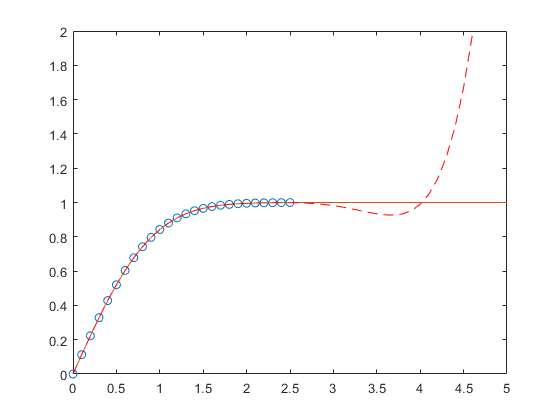


% In this interval, the interpolated values and the actual values agree fairly closely. Create a plot to show how outside this interval, the extrapolated values quickly diverge from the actual data.
x1 = (0:0.1:5)';
y1 = erf(x1);
f1 = polyval(p,x1);
figure
plot(x,y,'o')
hold on
plot(x1,y1,'-')
plot(x1,f1,'r--')
axis([0  5  0  2])
hold off